# carga_calibra

Lee un archivo estandar de la Base de Datos del proyecto InnovaAtletismo y devuelve un vector con acelerómetros `a_cal y g`iroscopios `g_cal `**calibrados con la convención ISB**, así como los cuaterniones originales `quat_cal,` y las partes de la señal que se consideran de interés, divididas en intervalos temporales de interés (de muestra inicial a final) , `Intervalos`.  

## Syntax

`[a_cal, g_cal, Intervalos, quat_cal]=carga_calibra(IDexp)`

`[a_cal, g_cal, Intervalos, quat_cal]=carga_calibra(IDexp, numSensor, Visualiza)`

## Description

`[``a_cal, g_cal, Intervalos, quat_cal``]=carga_calibra(``IDexp``) e`l parámetro de entrada `IDexp` se refiere al Identificador del Experimento, y se refiere a un archivo **αβ.mat ** (del proyecto InnovaAtletismo) y devuelve un vector con acelerómetros `a_cal y g`iroscopios `g_cal `**calibrados con la convención ISB**, así como los cuaterniones originales `quat_cal,` y las partes de la señal que se consideran de interés, divididas en intervalos temporales de interés (de muestra inicial a final) , `Intervalos`.  

En función del ID, además de los datos, se leen las condiciones que afectan al IMU concreto, que son:

- su localización: tres posibilidades, que son pie Derecho, pie Izquierdo y cintura-Sacro (D/I/S).

- su colocación: las posibilidades son tres: Empeine, Lateral y Talón (E/L/T). 

Si en el experimento se utilizaron varios IMUs, el usuario seleccionará estas opciones para seleccionar el IMU concreto de interés.

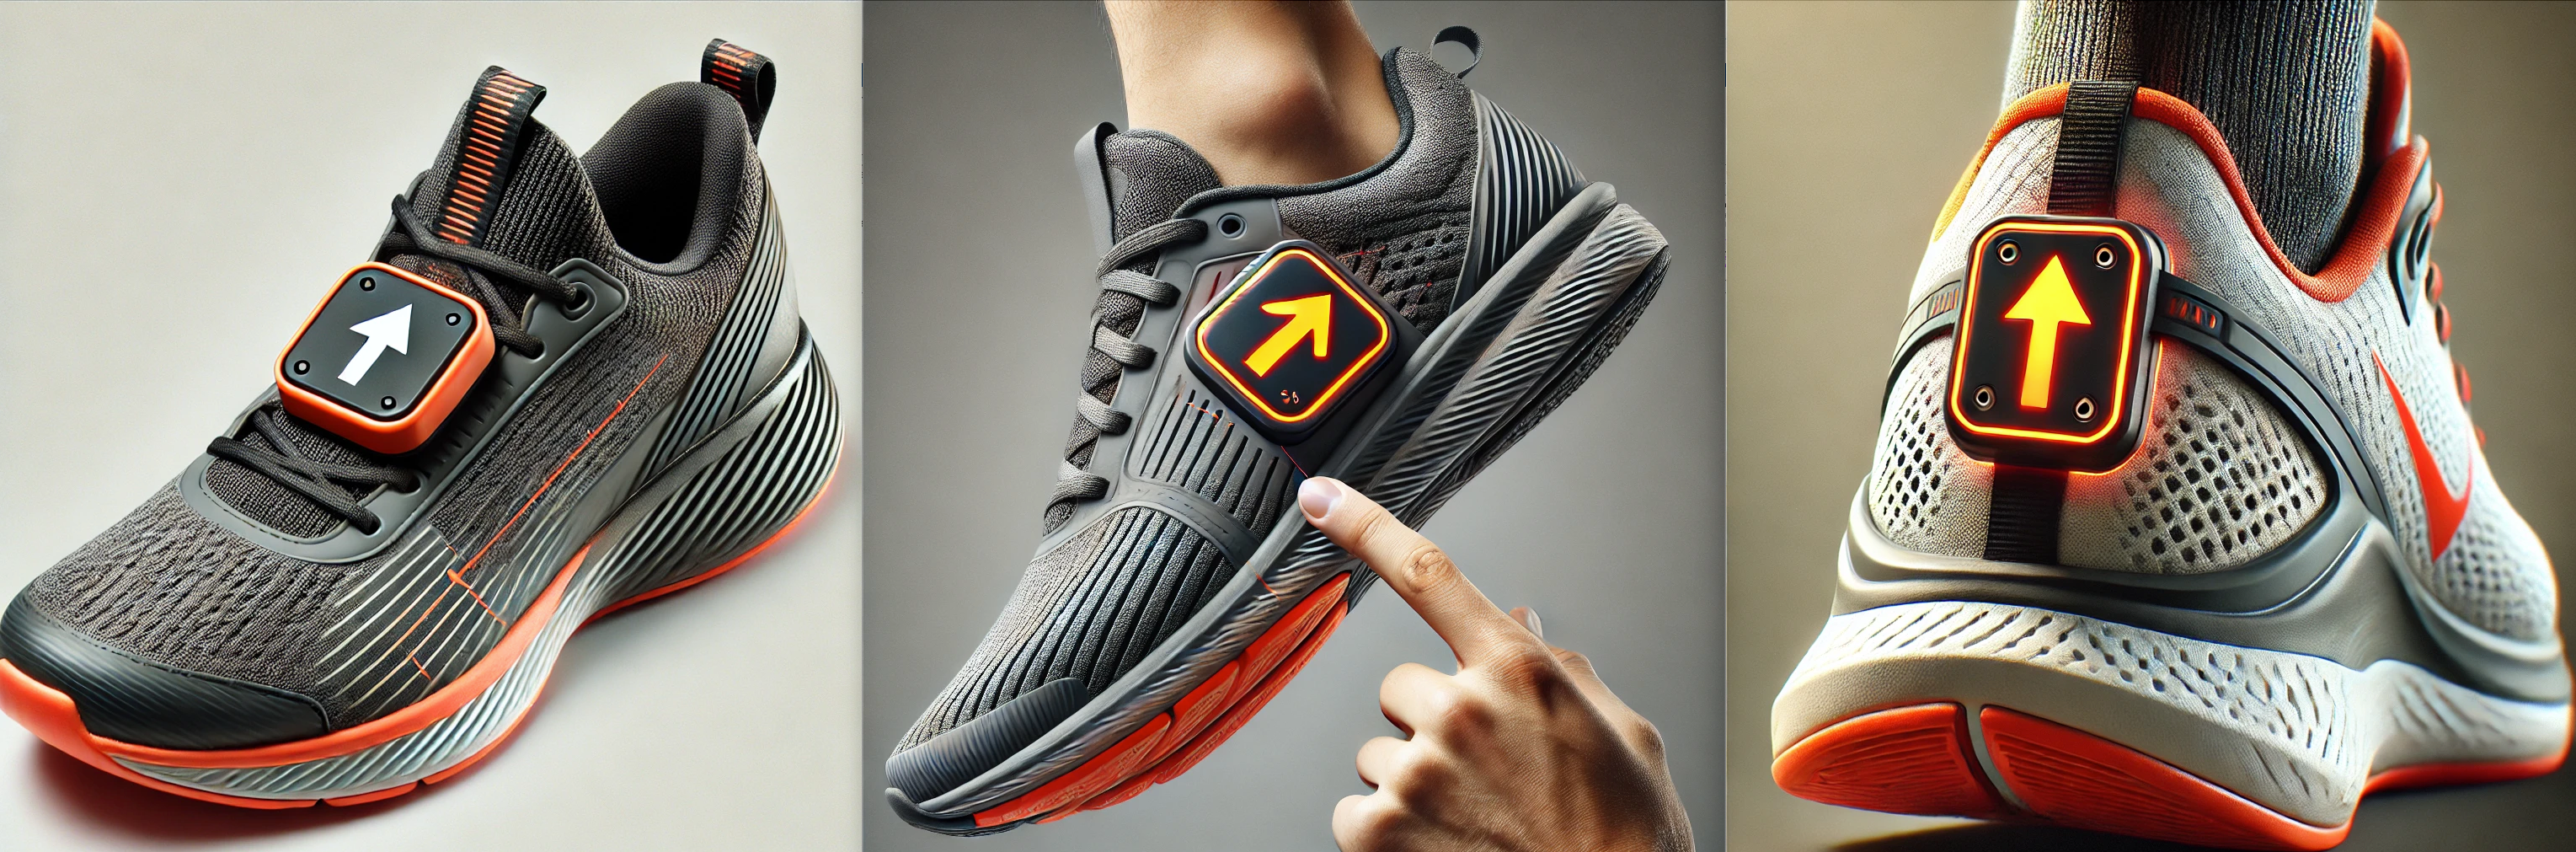

Todos estos parámetros están guardados en el archivo **αβ.mat **en las siguientes variables:

- `IntervalEstatico : `intervalo de muestras en las que no había movimiento, para calibración.

- `Intervalos` `:` intervalos de muestras de interés, una como mínimo.

- `Rcalib :` matriz (Nx3, N num. de IMUs); la fila describe la orientación del sensor *i* respecto al *convenio anatómico (V, ML, AP)*.

- `txt1` `:` etiqueta informativa sobre la posición de los IMUs, combinación de letras (D/I/S) (Dch, Iqd, Sacro)

- `txt2 :` etiqueta sobre la colocación de los IMUs, combinación de letras  (E/L/T/O) (Empeine, Lateral, Talón, Otra)

Si se escoge la opción de "Visualizar", se generan varias gráficas (se usa habitualmente para el primer ajuste de los parámetros en un nuevo experimento). En tal caso:

- Crea una figura con la señal completa de un acelerómetro.

- Crea otra figura con un tramo pequeño de un acelerómetro en el que se supone que el sensor estuvo reposo, para que el usuario pueda escoger un intervalo de muestras para alinear el sensor con la gravedad (llamando a la funcion calibra_anatomical).

- Crea una figura comparando las aceleraciones antes y después de la calibración.

Finalmente se alinea el sensor y se devuelve la señales alineadas de acelerómetro `a_cal `y del giróspoco `g_cal `con la convención ISB, y los quaterniones si existieran.

`[``a_cal, g_cal, Intervalos, quat_cal``]=carga_calibra(``IDexp``, ``numSensor, Visualiza``) e`l parámetro de entrada `numSensor` se refiere al Identificador del Sensor concreto con el que se va a trabajar:

- 1: pie derecho, 

- 2: pie izdo, 

- 3: COG 

El parámetro `Visualiza` permite dibujar el resultado de la calibración, opciones Si o No ('S', 'N'):

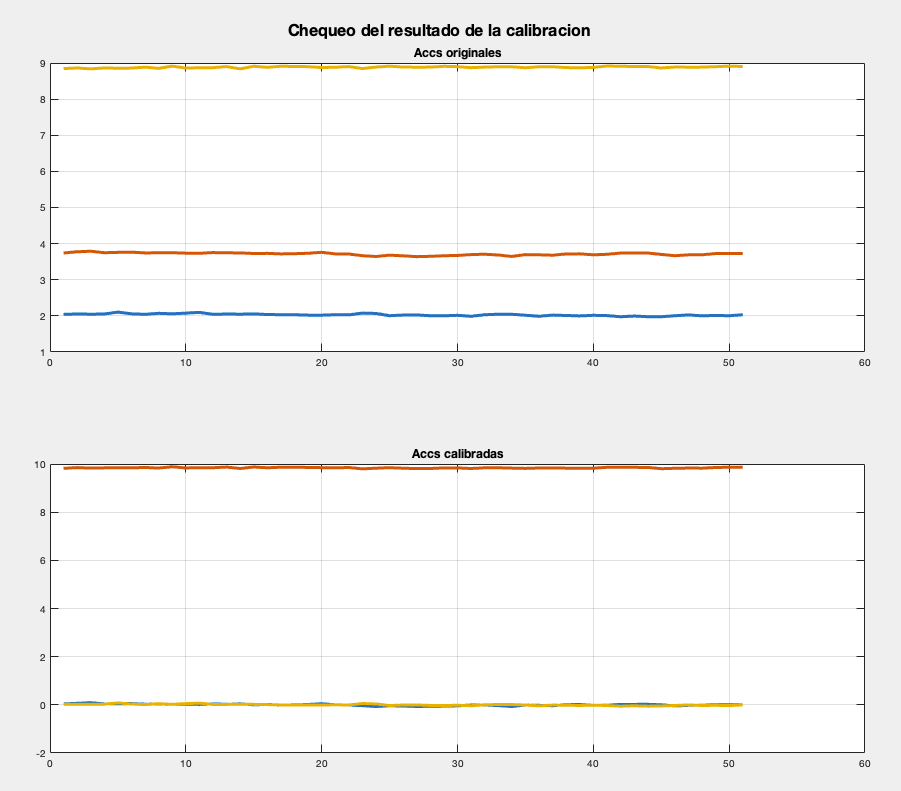

## Argumentos de entrada

- `IDexp              - Código de identificación del sensor (letra+numero)`

- `numSensor          - Entero que identifica el sensor Sensor (1,2,3), pie derecho, izdo o COG respect.`

- `Visualiza          - Opción de gráficas aux. para debugging ('S', 'N')`

## Argumentos de salida

- `a_cal              - Acelerómetros calibrados formato ISB`

- `g_cal              - Giroscopios calibrados formato ISB`

- `Intervalos         - Zonas de estudios, con muestra de inicio y final.`

- `quat_cal           - quaterniones dados por el sensor`

## Examples

% Lista de experimentos a analizar:
%
chars = {'a1', 'a2', 'a3','a4', 'a5', 'a6'};

for ch = chars
    [a_cal, g_cal, Intervalos]=carga_calibra(ch{1},1,'N');
    % utilización de los datos para algo:
    test_all_pie;
end
